After revising the simulation of ACh sensor experiment in the 2pFLIM settings (see script of this in **/Users/pingchuanma/Desktop/ChenLab_Data/MATLAB analysis/ACh_modified_simulation_20220722.mlx**), correspondingly I need to revise the FLP simulation (see before revised in **/Users/pingchuanma/Desktop/ChenLab_Data/MATLAB analysis/FLP_simulation_20220326.mlx **and **/Users/pingchuanma/Desktop/ChenLab_Data/MATLAB analysis/simulation_FLP.mlx**).

The major change will be:

- different tau1, tau2 

- Gen_pop function generates a 512-channel population, no peak shift

- prf convolution

- different wrap around because of 512 channels

% give this simulation a name
SimulationName='simulation_ACh_20220728';
savefolder='/Users/pingchuanma/Desktop/ChenLab_Data/';

% create the simulation folder
cd(savefolder)
mkdir(SimulationName)

% go to the simulation folder
filepath=[savefolder SimulationName '/']

filepath = '/Users/pingchuanma/Desktop/ChenLab_Data/simulation_ACh_20220728/'

cd(filepath)

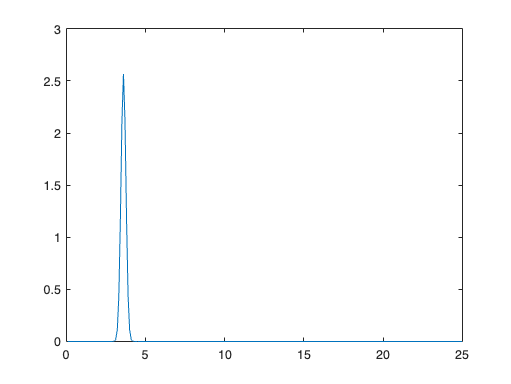

% guassian fitting curve, used what's from before
width=0.1554;
miu=3.6133;
x=1:1:256;
x=x*(25/256);
Gaussian_y=1/(width*sqrt(2*pi))*exp(-(x-miu).^2/(2*width^2));
figure
plot(x,Gaussian_y)

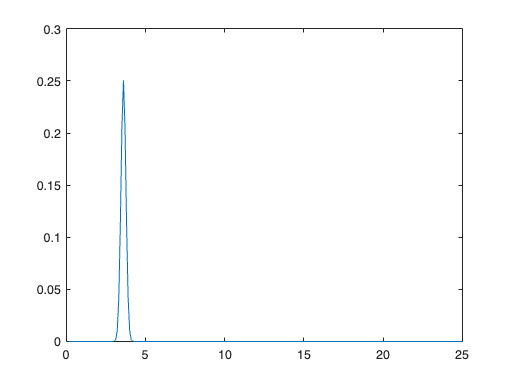

Gaussian_y=Gaussian_y/sum(Gaussian_y);
figure
plot(x,Gaussian_y)


Gaussian_y=Gaussian_y';

p1_samples=0.6:0.02:1.0; % simulate the p1 range from 0.6 to 1.0
AF=20000;
tau1=2.6199;
tau2=0.9221;
DC=1000;
afterpulse=0.01;

SS_samples=20000:20000:500000; % simulated sample size range from 20000 to 500000.

global Gaussian_y


for i=1:21
    p1=p1_samples(i);
    p2=1-p1;
    PopulationName=['Simulation_20220728_FLP_population_',num2str(p1),'.mat'];
    GenPop512_FLP(100000, p1, p2, tau1, tau2, PopulationName); 
    for j=1:25
        SS=SS_samples(j);
        mkdir([num2str(SS),'_',num2str(p1)])
        for k=1:50
            samplename=[num2str(SS),'_',num2str(p1),'/',num2str(k),'_noauto.mat'];
            FLIMsim512_FLP(SS,DC,afterpulse, PopulationName,samplename)
        end
    end
end

p1_samples=0.6:0.02:1.0; % simulate the p1 range from 0.6 to 1.0
AF=20000;
tau1=2.6199;
tau2=0.9221;
DC=1000;
afterpulse=0.01;

SS_samples=20000:20000:500000; % simulated sample size range from 20000 to 500000.

global Gaussian_y

c=parcluster()

c = 

 Local Cluster

    Properties: 

                   Profile: local
                  Modified: false
                      Host: Pingchuans-MacBook-Pro
                NumWorkers: 16
                NumThreads: 1

        JobStorageLocation: /Users/pingchuanma/Library/Application Support/MathWorks/MATLAB/local_cluster_jobs/R2022a
   RequiresOnlineLicensing: false

    

for i=2%:10
    batch('FLP_simulation_batch')
end

ans = 

 Job

    Properties: 

                   ID: 4
                 Type: independent
             Username: pingchuanma
                State: running
       SubmitDateTime: 28-Jul-2022 00:02:24
        StartDateTime: 
      RunningDuration: 0 days 0h 0m 0s
           NumThreads: 1

      AutoAttachFiles: true
  Auto Attached Files: 

ch=1;
for i=1:21
    p1=p1_samples(i);
 

    for j=1:25
        SS=SS_samples(j);
%         mkdir([num2str(SS),'_',num2str(p1),'_auto'])
        
        tau_avg=[];
        tau_avgTrunc=[];
        tau_empTrunc=[];
        photoncount=[];
        p1_sim=[];
        chi2=[];
        beta2=[];
        beta4=[];
        beta5=[];
        beta6=[];
        lifetime_histograms=[];
        peak_beforeC=[];
        peak_afterC=[];
        peak_withauto=[];
        
        for k=1:50
            
            AFname=['20000_AF/',num2str(k),'_auto.mat'];
            load(AFname);
            n_auto=n2';
            
            samplename=[num2str(SS),'_',num2str(p1),'/',num2str(k),'_noauto.mat'];
            load(samplename)
            n_ACh=n';
            spc.lifetimes{1}=n_ACh+n_auto+6;
            
            
            spc_fitexp2gaussGY(ch);
%             spc_adjustTauOffset(1);
            
            
            photoncount(k)=sum(spc.lifetimes{1});
            p1_sim(k)=spc.fits{ch}.beta1/(spc.fits{ch}.beta1+spc.fits{ch}.beta3);
            tau_avg(k)=spc.fits{ch}.avgTau; % mean Tau calculated from fit
            tau_avgTrunc(k)=spc.fits{ch}.avgTauTrunc;
            tau_empTrunc(k)=spc.fits{ch}.EmpTauTrunc;
            chi2(k)=spc.fits{ch}.redchisq;
            beta2(k)=spc.fits{ch}.beta2;
            beta4(k)=spc.fits{ch}.beta4;
            beta5(k)=spc.fits{ch}.beta5;
            beta6(k)=spc.fits{ch}.beta6;
            lifetime_histograms=[lifetime_histograms spc.lifetimes{1}];
            peak_beforeC(k)=mean(find(n1==max(n1)));
            peak_afterC(k)=mean(find(n2==max(n2)));
            peak_withauto(k)=mean(find(spc.lifetimes{1}==max(spc.lifetimes{1})));
            
        end
        
        photoncount=transpose(photoncount);
        tau_avg=transpose(tau_avg);
        tau_avgTrunc=transpose(tau_avgTrunc);
        tau_empTrunc=transpose(tau_empTrunc);
        p1_sim=transpose(p1_sim);
        chi2=transpose(chi2);
        beta2=transpose(beta2);
        beta4=transpose(beta4);
        beta5=transpose(beta5);
        beta6=transpose(beta6);
        
        result_name=[num2str(SS),'_',num2str(p1),'_result.mat'];
        save(result_name,'photoncount', 'tau_avg','tau_avgTrunc','tau_empTrunc', 'p1_sim','chi2','beta2','beta4','beta5','beta6','lifetime_histograms')
    end
end

Error using load
'20000_AF/1_auto.mat' is not found in the current folder
or on the MATLAB path, but exists in:
    /Users/pingchuanma/Desktop/ChenLab_Data/simulation_ACh_20220727

Change the MATLAB current folder or add its folder to
the MATLAB path.